# example for calculating solar radiation pressure (SRP) 

clc
clear
close all

## parameters

const = orbitConst; % constant parameters for orbit

## read object

sat = readSC('boxWing.obj',2)

Reading Object file : boxWing.obj
  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
Reading Material file : boxWing.mtl
  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    332     3


sat = フィールドをもつ struct :
    vertices: [242×3 double]
       faces: [332×3 double]
        area: [332×1 double]
         pos: [332×3 double]
      normal: [332×3 double]
          Ca: [332×1 double]
          Cd: [332×1 double]
          Cs: [332×1 double]


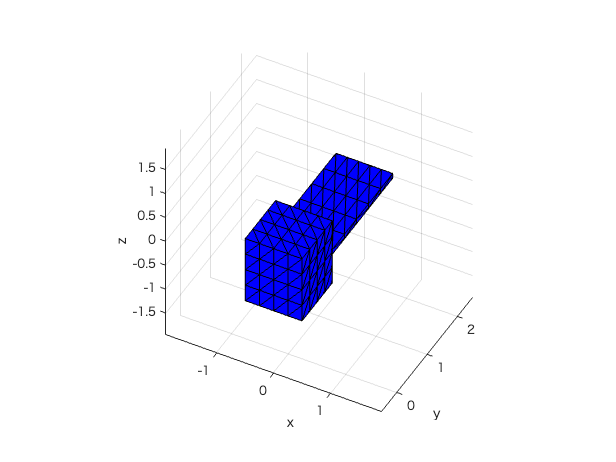


% check satellite shape
showSC(sat)

## set illumination condition

d = au2km(1.0,const) * 10^3; % distance between satellite and Sun, m
sunB = [0 0 1]; % sun direction from satellite expressed with body-fixed frame

## calculation

sat = srpLps(sat, sunB, d, const)

sat = フィールドをもつ struct :
    vertices: [242×3 double]
       faces: [332×3 double]
        area: [332×1 double]
         pos: [332×3 double]
      normal: [332×3 double]
          Ca: [332×1 double]
          Cd: [332×1 double]
          Cs: [332×1 double]
       force: [332×3 double]
      torque: [332×3 double]


sat.force % SRP forces at each facet, N, nx3 matrix

ans = 1.0e-06 *

         0         0   -0.2735
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


sat.torque % SRP torques at each facet, Nm, nx3 matrix

ans = 1.0e-06 *

    0.0912   -0.0912         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0



sum(sat.force,1) % total SRP force expressed with body-fixed frame

ans = 1.0e-04 *

         0         0   -0.2625


sum(sat.torque,1) % total SRP force expressed with body-fixed frame

ans = 1.0e-04 *

   -0.2625         0         0
